# **EEG Data Acquisition**

## **DREAMER Dataset**

### **Step 1: Load the dataset**

% Read the dataset
% The 'DREAMER' variable will be available as soon as dataset is loaded
load('C:/UserData/OneDrive/PersonalProjects/18_human-emotion-recognition-based-on-eeg/dataset/dreamer/DREAMER.mat');

% Display the information of dataset
disp(DREAMER);

                  Data: {1×23 cell}
      EEG_SamplingRate: 128
      ECG_SamplingRate: 256
        EEG_Electrodes: {'AF3'  'F7'  'F3'  'FC5'  'T7'  'P7'  'O1'  'O2'  'P8'  'T8'  'FC6'  'F4'  'F8'  'AF4'}
          noOfSubjects: 23
    noOfVideoSequences: 18
            Disclaimer: 'While every care has been taken to ensure the accuracy of the data included in the DREAMER dataset, the authors and the University of the West of Scotland dataset do not provide any guarantees and disclaim all responsibility and all  liability (including without limitation, liability in negligence) for all expenses, losses, damages (including indirect or consequential damage) and costs which you might incur as a result of the provided data being inaccurate or incomplete in any way and for any reason. 2017, University of the West of Scotland, Scotland, United Kingdom'
              Provider: 'University of the West of Scotland'
               Version: '1.0.2'
       Acknowledgement: 'The authors would like t

### Step 2: Visualize data

The dataset consisting of 18 film clips selected and evaluated by Gabert Qullen. The "Data" field is the 14-channel EEG signal of 23 volunteers. 

For example, plot the EEG signal of the first volunteer in dataset

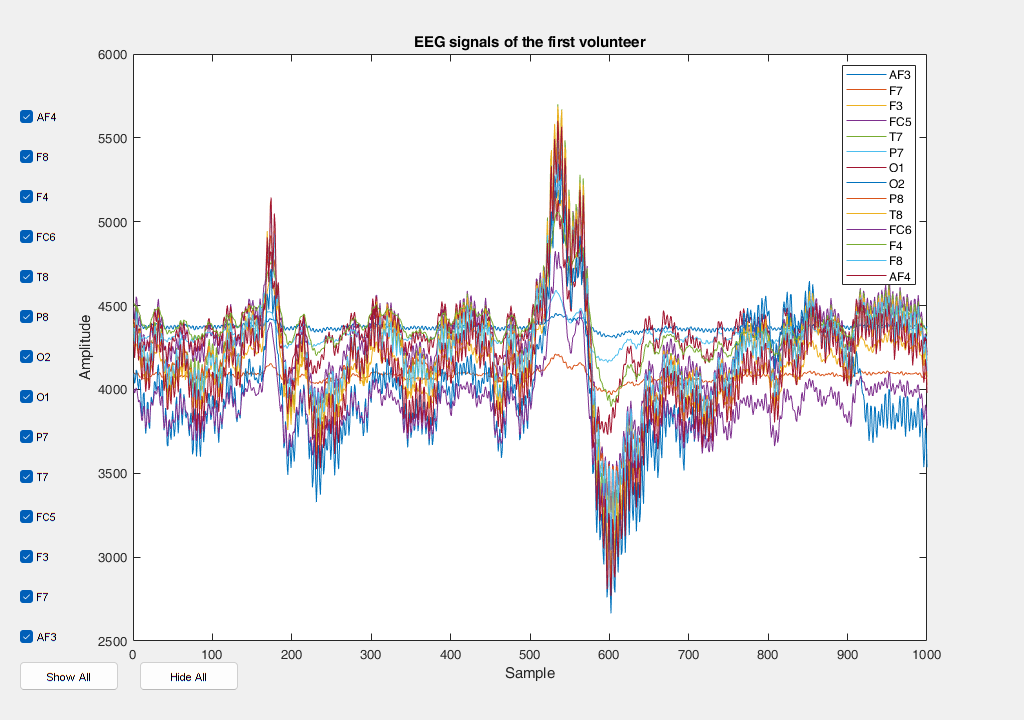

figure('NumberTitle', 'off', 'Name', 'EEG Signals', 'Position', [0, 0, 1024, 720]);
h = plot(DREAMER.Data{1, 1}.EEG.baseline{1, 1}(1:1000, :));

xlabel('Sample');
ylabel('Amplitude');
title('EEG signals of the first volunteer');
channels = {'AF3', 'F7', 'F3', 'FC5', 'T7', 'P7', 'O1', 'O2', 'P8', 'T8', 'FC6', 'F4', 'F8', 'AF4'};
legend(channels);

% Create checkboxes
checkboxes = gobjects(length(channels), 1);
for i = 1:length(channels)
    checkboxes(i) = uicontrol('Style', 'checkbox', 'String', channels{i}, ...
        'Position', [20, 70 + (i-1)*40, 50, 30], 'Value', 1, ...
        'Callback', @(src, event) set(h(i), 'Visible', bool2str(get(src, 'Value'))));
end

% Create "Show/Hide All" button
selectAllButton = uicontrol('Style', 'pushbutton', 'String', 'Show All', ...
    'Position', [20, 30, 100, 30], 'Callback', @(src, event) toggleAll(true, checkboxes, h));

deselectAllButton = uicontrol('Style', 'pushbutton', 'String', 'Hide All', ...
    'Position', [140, 30, 100, 30], 'Callback', @(src, event) toggleAll(false, checkboxes, h));


% Hàm để chọn hoặc bỏ chọn tất cả các checkbox

function toggleAll(selectAll, checkboxes, h)
    for j = 1:length(checkboxes)
        set(checkboxes(j), 'Value', selectAll);  % Cập nhật trạng thái checkbox
        set(h(j), 'Visible', bool2str(selectAll));  % Cập nhật hiển thị đường dẫn tương ứng
    end
end
function str = bool2str(val)
    if val
        str = 'on';
    else
        str = 'off';
    end
end